# Trading Card Domain

I decided to use images of physical trading cards (e.g. pokemon).

## Initialize

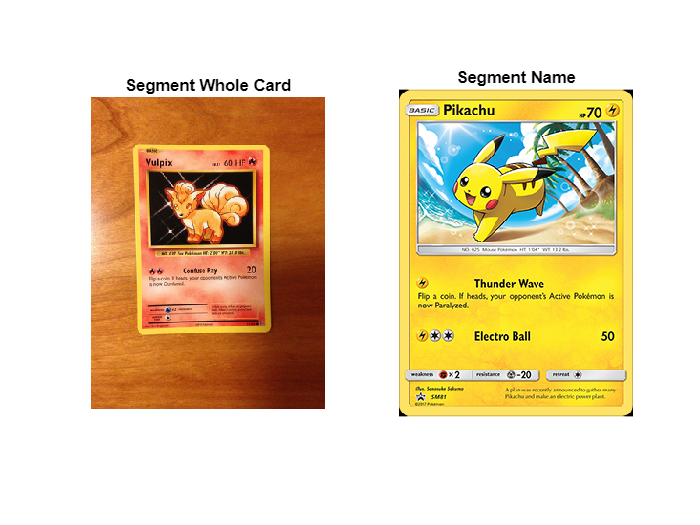

img_path = "images/final/task_1/";

img_pika = imread(img_path + "pokemon_pikachu.png");
img_vulpix = imread(img_path + "pokemon_vulpix.png");

subplot(1,2,1); imshow(img_vulpix); title("Segment Whole Card");
subplot(1,2,2); imshow(img_pika); title("Segment Name");

### Segment Card from Background - Vulpix

First we make sure we isolate the card from the rest of the background.

#### Edge Detection - Canny

figure; rows=2; cols=2;
subplot(rows, cols, 1); imshow(img_vulpix); title("original");
img_edge = rgb2gray(img_vulpix);
edge_thresh = 0.34;
img_bw = edge(img_edge, 'canny', edge_thresh); %rgb2gray(img_vulpix)
img_bw_closed = imclose(img_bw, strel('line', 4, 45));

subplot(rows, cols, 2); imshow(img_bw); title("1. Edge Detection - canny");
subplot(rows, cols, 3); imshow(img_bw_closed); title("2. Closing");

% TODO: align image to be in portrait mode so that cropping can be done successfully
% Rotate based on orientation
%labeledImage = logical(img_bw);
%measurements = regionprops(labeledImage, 'Orientation');
%rotatedImage = imrotate(img, -90 + -measurements(1).Orientation);
%subplot(rows, cols, 3); imshow(rotatedImage); title("Rotated image");

#### Boundary Extraction - bwboundaries

TODO: Use these bounds to extract corners

line_width = 3;

[Bounds, Labels] = bwboundaries(img_bw);
bounds_labels = label2rgb(Labels, @jet, [.5 .5 .5]);

%subplot(rows, cols, 3); imshow(bounds_labels); title("2. Extract Boundaries");\
%hold on; % retain current plot
%for k = 1:length(Bounds)
%   boundary = Bounds{k};
%   plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', line_width)
%end

#### Corner Extraction - Hough Transform

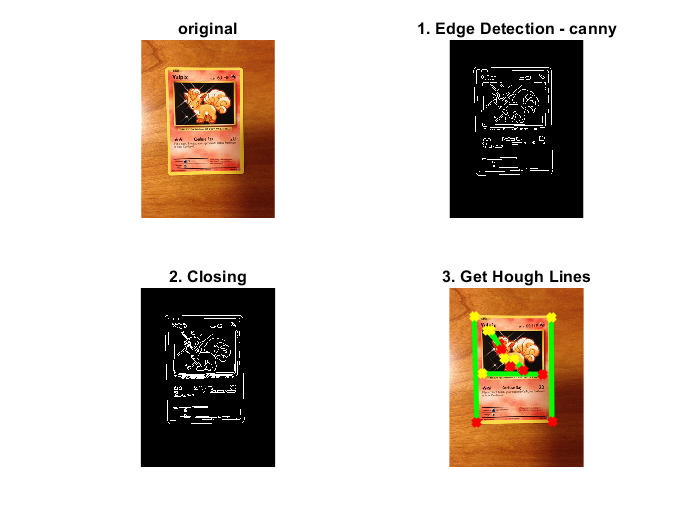

% Get transform
rho = 4;
[H,T,R] = hough(img_bw,'RhoResolution', rho, 'Theta', -90:0.5:89);

% Get peaks
num_of_peaks = 5;
P = houghpeaks(H, num_of_peaks, 'threshold', ceil(0.3*max(H(:))));

% Get lines
fillgap = 5;
min_len = 20;
lines = houghlines(img_bw, T, R, P, 'FillGap', fillgap, 'MinLength', min_len);
subplot(rows, cols, 4); imshow(img_vulpix); title("3. Get Hough Lines");

hold on
all_lines = {0, 0, 0}; % point1 (x1, y1), point2 (x2, y2), length (x1-x2, y1-y2)
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   % Add line to list
   all_lines{k, 1} = lines(k).point1;
   all_lines{k, 2} = lines(k).point2;
   all_lines{k, 3} = abs(lines(k).point1 - lines(k).point2);
   % len = norm(lines(k).point1 - lines(k).point2);

   plot(xy(:,1),xy(:,2),'LineWidth', line_width, 'Color', 'green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',line_width,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',line_width,'Color','red');
end

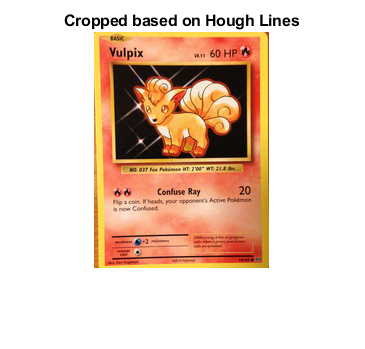

% Get 2 leftest/rightest lines' points (Vertical Lines)
left_line = [all_lines{1, 1}, all_lines{1, 2}];
right_line = [all_lines{1, 1}, all_lines{1, 2}];
x_len = 0;
y_len = 0;
for i=1:length(all_lines)
    xy1 = all_lines{i, 1};
    xy2 = all_lines{i, 2};

    if (xy1(1) > right_line(1) || xy2(1) > right_line(1))
        right_line = [xy1, xy2];
    end

    if (xy1(1) < left_line(1) || xy2(1) < left_line(1))
        left_line = [xy1, xy2];
    end

    x_len = abs(max(right_line(1), right_line(3)) - min(left_line(1), left_line(3)));
    y_len = abs(max(right_line(2), right_line(4)) - min(left_line(2), left_line(4)));
end

% Crop based on the corners
bbox_rect = [left_line(1), left_line(2), x_len, y_len];
img_bbox_crop = imcrop(img_vulpix, bbox_rect);
figure; imshow(img_bbox_crop); title("Cropped based on Hough Lines");

### Segment Name - Pikachu

The name of the pokemon will always appear at the top of the card. Therefore, extract all the text possible from the card and retrieve the text on the top-most left area.

#### extract the text from area of interest

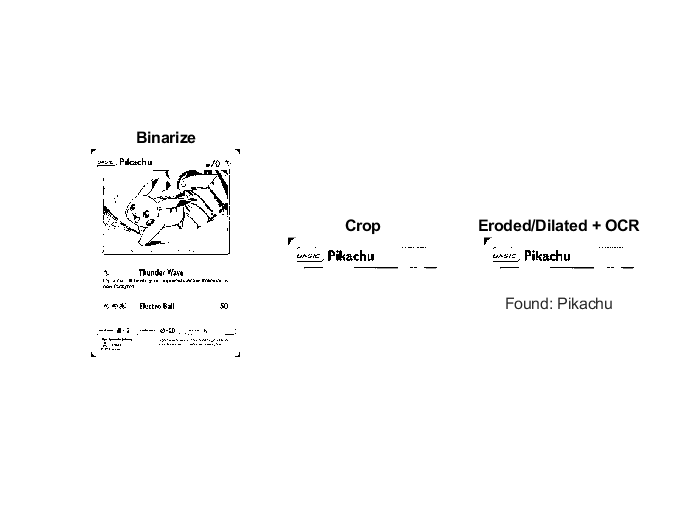

figure; rows=1; cols=3;

% Binarize
sens_threshold = 0.9;
img_bw_pika = imbinarize(rgb2gray(img_pika), "adaptive", "Sensitivity", sens_threshold);

% Get region/area of interest
region_per = 15/100; % estimated percentage covering the name area
crop_rec = [0.5 0.5 (x_len - 1) (y_len * region_per)];
img_cropped = imcrop(img_bw_pika, crop_rec);

% Region-growing method
%nr_of_iterations = 500;
%mask_contour_region = zeros(size(img_cropped));
%mask_contour_region(25:end-25,25:end-25) = 1;
%mask = activecontour(img_cropped, mask_contour_region, nr_of_iterations, 'edge');
%masked_img = bsxfun(@times, img_cropped, cast(mask, 'like', img_cropped));

% Erode/Dilate (Dilate because text is black/in background) - To separate
% thin connections between letters if they exist
img_eroded = imdilate(img_cropped, strel('arbitrary', 4));

% Use OCR to extract visible text
ocr_words = ocr(img_eroded, crop_rec);

% Check if any of the results is a pokemon name
pokemon_name = "";
for i=1:size(ocr_words.Words)
    word = convertCharsToStrings(ocr_words.Words{i});
    % Check if any words found are a pokemon name
    pokemon_name = findPokemonByName(word);

    if (not(strcmp(pokemon_name, "not found.")))
        break;
    end
end

subplot(rows, cols, 1); imshow(img_bw_pika); title("Binarize");
subplot(rows, cols, 2); imshow(img_cropped); title("Crop");
subplot(rows, cols, 3); imshow(img_eroded); title("Eroded/Dilated + OCR");
xlabel("Found: " + pokemon_name);

## Questions

**1. Which domains did you choose and what is the goal of your segmentation?**

- Trading Card Game - Extract Card Information

**2. For morphological operators, specify the structuring element used. For region-growing, show the mask used.**

- **Closing (Line):**  To fix broken boundaries in case canny edge-detection could not properly separate the boundary from the background

- **Erode/Dilate (Arbitrary):** To separate tiny connections in the text

- **Region Growing (Active Contour):** To separate the card from the background

**3. Compare the performance of the different techniques. Which methods give you better results?**

- Region-growing did not work well for isolating the card from the background, since even with 10k iterations it does not manage to smoothly segment it. Therefore, used edge detection and Hough Lines to find the correct cropping region.